# Radar Array Optimization 

Written by team ArrAnt

University of Colorado Colorado Springs

Members:

-  Cynthia Valentine

-  Joseph Russ

-  Brianna McCague

-  Brett Ford

For and under the guidance of Northrop Grumman

 % Overview
 % Parameters inputed in the live script will be used in the radar_optimization script to create the population of pareto optimal solutions for radar arrays. 
 % The live script uses the optimization_output script to display a table and a graph of the solutions based on those paramaters.

 

 % Paramaters
 k= 0.6; % efficiency of attenae
 nu = 3;  % frequency (GHz) which is converted to meters for the loop gain
  
 number_of_styles = 3; % The number of distinct styles of radar array antennas that are permitted in the array  
 minimum_recievers_styles = 1; % the minimum number of styles that must to be recievers
 minimum_transmitter_styles = 1; % the minimum number of styles that must to be transmitters

 min_diameter = 1;
 max_diameter = 40; % The maximum diamater (meters) of any given antenna in the array
    
 min_quantity =  1;
 max_quantity = 80; % The maximum quantity of antennas of one style in the array
      
 min_power = 100;
 max_power = 500000; % The maximum power (watts) for each antenna in the array
 
 maximum_elements = 400; % The maximum total number of antennas in the array

 loop_gain_desired = 200; % The desired loop gain (dB) for the array
 
 year = 2030; % the year the array intends to be built

 include_monostatic = "F"; % change to a T to include monostatic antennas, change to a F to exclude monostatic antennas

This calls the function to optimize the array based on the paramaters entered above.

gamultiobj stopped because it exceeded options.MaxGenerations.


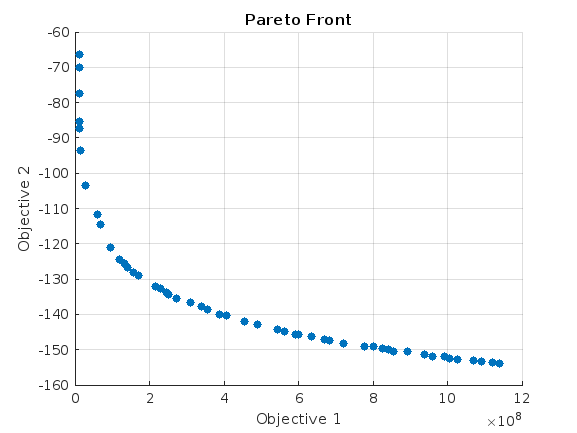


 [x, operative_values] = radar_optimization(number_of_styles, minimum_transmitter_styles, minimum_recievers_styles, min_quantity, max_quantity,min_diameter, max_diameter, min_power, max_power,year,include_monostatic,k,nu,maximum_elements);

include_monostatic = "F"

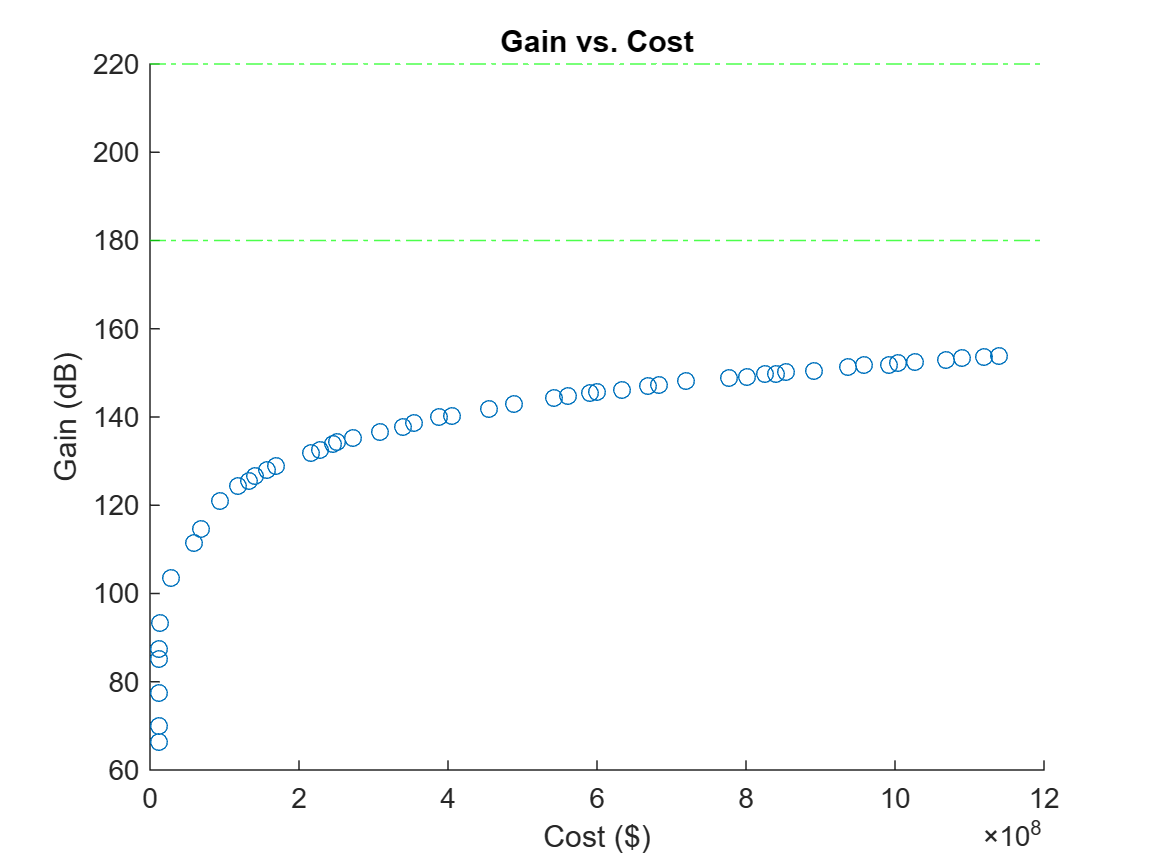

table = 53x14 table
        Type 1         Quantity 1    Diameter 1 (m)    Power 1 (W)       Type 2       Quantity 2    Diameter 2 (m)    Power 2 (W)       Type 3       Quantity 3    Diameter 3 (m)    Power 3 (W)     Cost ($)     Gain (dB)
    _______________    __________    ______________    ___________    ____________    __________    ______________    ___________    ____________    __________    ______________    ___________    __________    _________

    {'Transmitter'}         1              15                 1

parameters, table = optimization_output(x,number_of_styles, operative_values, include_monostatic, loop_gain_desired)

opt_output = optimization_output;
table = opt_output.createTable(obj,x,number_of_styles, operative_values, include_monostatic);

Unrecognized function or variable 'obj'.

 %optimization_output(x,number_of_styles, operative_values, include_monostatic, loop_gain_desired).saveCSV